# U model for land sink

Prof Colin Prentice; Dr Trevor Keenan; Dr Cesar Terrer; Dr Oskar Franklin; Huanyuan Zhang

Created 15/02/2019 

last edited 24/05/2019

**To run the code, please check everything written in the chapter "OPTION" is correct.**

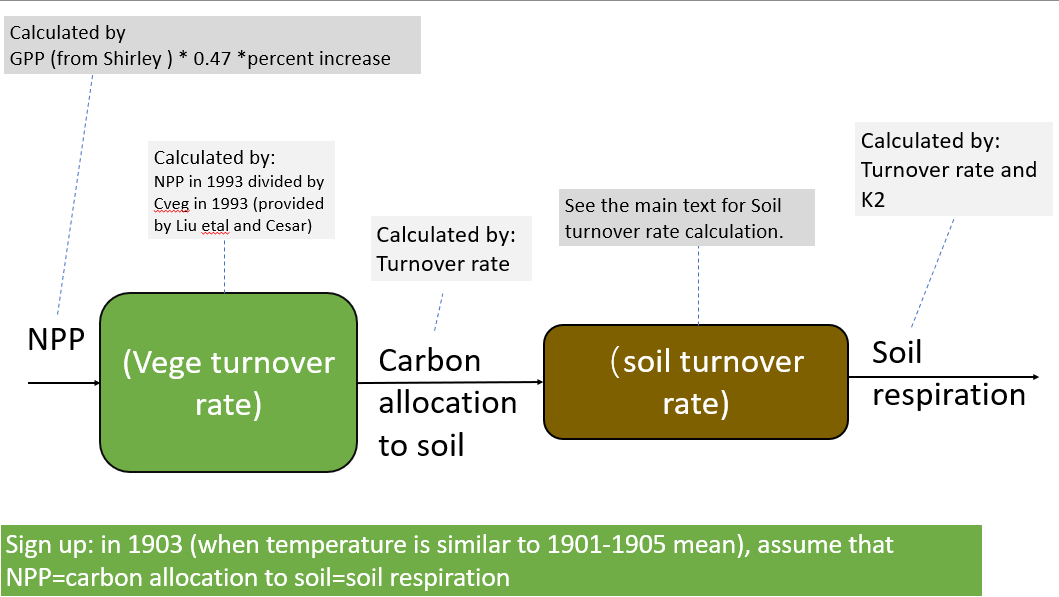

# 2. Input data

## NPP in each year

NPP in each year was calculated based on the u equation.


$$\frac{NPP}{NPP_{ref}}=(\frac{C_{a}}{C_{a} + u})\div (\frac{C_{ref}}{C_{ref} + u})$$



$${NPP_{ref}=GPP_{1996-2007}*0.47$$


(C_a is air temperature in a sepecific year, NPP is the averaged NPP flux in the corresponding year, C_ref is 372 ppm, denoted by a red line in figure 2)

NPP_ref is NPP under 372ppm, which is at the middle of 1996-2007.

Reference NPP is calculated by 0.47*reference GPP. We adopt P model NPP 1997-2006 mean as reference NPP, provided by Shirley, not Trendy because trendy resolution is only 1 dgree. 

we derived the constant u from Cesar's percentage increase map (average u is about 120 (Tropical forest is about this range)).

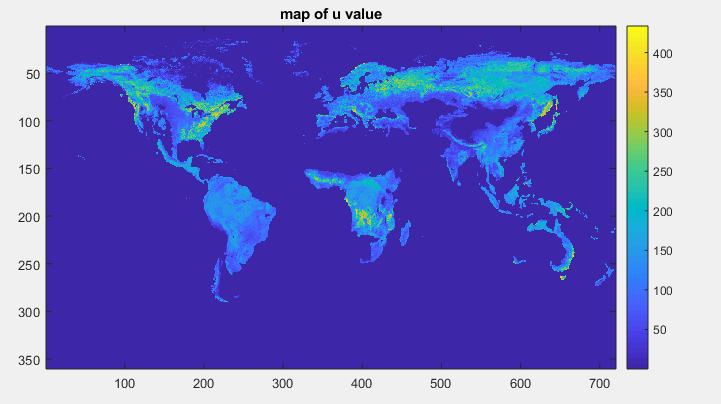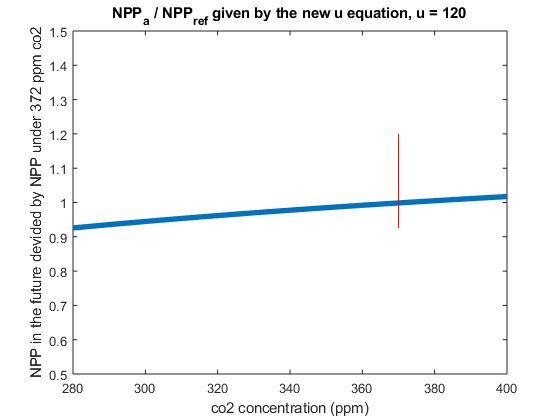

Figure 1 U value distribution, lower value cause slower NPP increasing rate.         

Figure 2, NPP compared with NPPref under 280 (1903) - 400 (current) ppm of CO2

## CO2 record

1959–2017 data is from [Direct measurements of CO2 at Mauna Loa Observatory](ftp://aftp.cmdl.noaa.gov/products/trends/co2/co2_annmean_mlo.txt)

1850-1958 data is from [ice cores](http://data.giss.nasa.gov/modelforce/ghgases/Fig1A.ext.txt)

1800-1850 CO2 data is from [Law Dome ice cores](http://www1.ncdc.noaa.gov/pub/data/paleo/icecore/antarctica/law/law_co2.txt) (75 year smoothed).

## Reference Cveg and vegetation turnover time K1

Total vegetation biomass Cveg in 1993 is shared by Cesar from[ Liu et al 2015](http://wald.anu.edu.au/global-biomass/)


$$$K_1=\frac{C_{veg1993}}{NPP_{1993}{$$
 

Then we derived turnover rate by the above equation. K1 is a map and unchanged through time.

Then we get the initial Cveg: $$C_{veg1903}=K1* NPP_{1903}$$

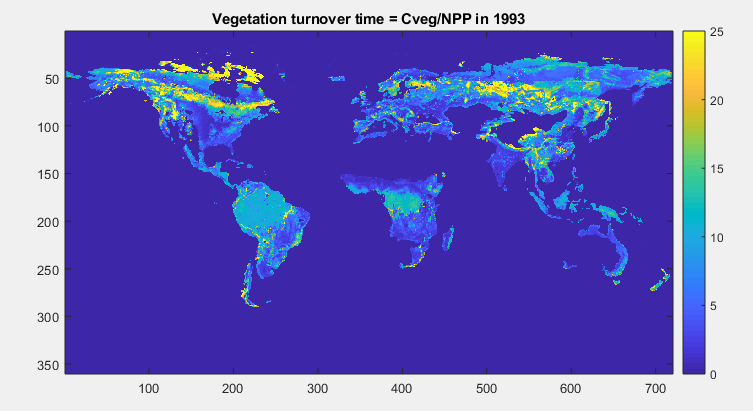

## Reference Csoil ans Soil carbon turnover rate K2

(i) denotes the variable is a global map, (i,t)denotes the map change through time.

We assume steady state in 1903, therefore, NPP1903=Soil Respiration 1903, and we have:


$$$Soil,Respiration(i,t)=K_2*C_{soil}(i,t)*f_{Q10} (Temp(i,t))$$$


We first assume $$\sum_{}^{} C_{soil}(i,1903)=1500 PgC$$

Then we calculate K2 via $$K2=\sum(\frac{NPP(i,1903)}{f_{Q10}(T(i,1903))})\div\sum_{}^{} C_{soil}(i,1903)$$

Then we get a map of Csoil based on the geographical distribution of both NPP and temperature.

$$C_{soil}(i,1903)=\frac{NPP(i,1903)}{f_{Q10}(T(i,1903))}*K_2$$ , alternatively, we once got Csoil from soilgrid but it turns out to be worse than the assumption.

For Q10 function:

$$f_{Q10}=Q10^{(T-T_{ref})/10}$ where Q10 is set as 1.4 according to [Mahecha et al 2010](https://science.sciencemag.org/content/329/5993/838.full)

Alternatively, we once used $$f_{LT}=exp(E_0(\frac{1}{T_{ref}-T_0}-\frac{1}{T-T_0}))$. It was abondoned because respiration under this equation is too sensitive to warming.

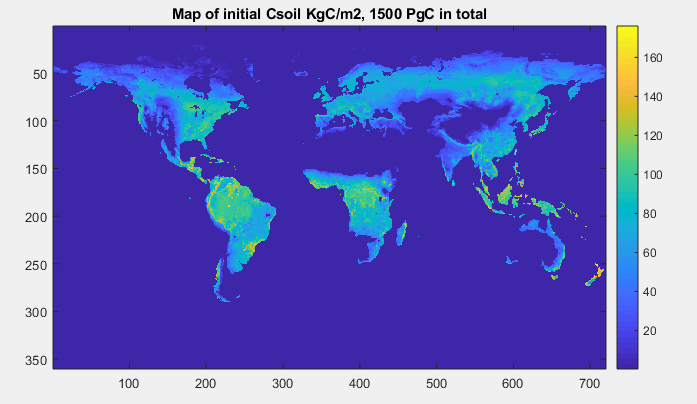

## Temperature Record

Downloaded from [CRU](https://crudata.uea.ac.uk/cru/data/hrg/)

- Yearly_temp use a series of yearly maps as temperature input

- Constant_temp use temperature in 1901 for any year (use the same temperature map throughout)

## After pulling in all data, I check every pixel to see whether the pixel is missing any map...remove if yes

This actually made us loose 10% of pixels!!

# 3. Assumption

- Heterotrophic respiration = soil respiration

- constant vegetation turnover rate

- In 1903 (same as 1901-1905 MAT mean), land sink =0 (maybe problematic for wetland)

- Total Csoil in 1903 = 1500PgC or Csoil at the moment = Csoil in 1903

- We disregard land use change etc in this simulation, (well this is not assumption, but we are just looking at the land sink caused by CO2 fertilization and warming)

- Air temperature was used for soil respiration etimation. Assume homogeneity of soil carbon (this is OK for our model, see discussion in past email) 

- the relationship between NPP and CO2 (i.e. the fertilization effect) can be descriped as:$NPP=f(light,etc)(\frac{C_{a}}{C_{a} + u})$ which is a saturation curve.

# 4. Model run

The initial temperature is set as average temperature from 1901 to 1905 (as this temperature is very close to MAT in 1903, therefore we started simulation from 1903).

Aterward, CO2 vary year to year and correspondingly, NPP vary year to year which change C_soil and C_veg every year.

The model runs on yearly timestep in below loop:

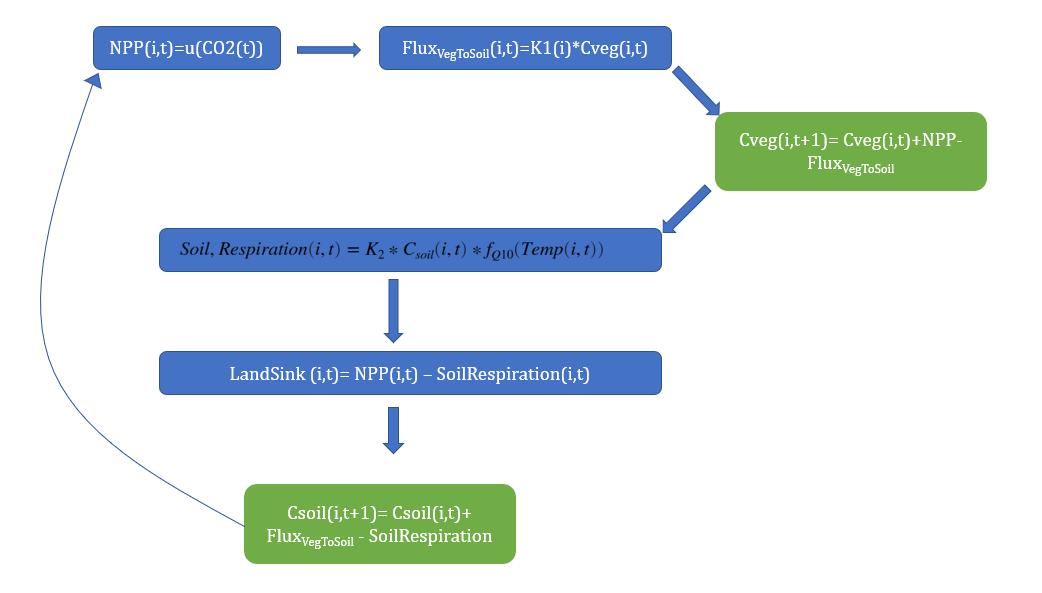

# Codes and Output

## Option

if exist('Annual_record','var')
else
clc
close all
clear
Path = 'I:\Imperial_college\Master_Project\New_model\u_model_masterfile.mlx'; %the directory of the script
Path = [fileparts(Path),filesep'];%get the directory of the current script
cd(Path)
C_soil_option='Assume_1500PgC';
Soil_respiration_equation='Q10'; 

## Run model under "constant temperature" and "yearly temperature"

By setting either "constant temperature" or "yearly_map", we make soil respiration respond to "carbon fertilization only" OR "both carbon and temperature".

Annual_record{1} = umodel_core_newvege (Path,'constant_temperature',Soil_respiration_equation,C_soil_option); %Only carbon fertilization effect
Annual_record{2} = umodel_core_newvege (Path,'yearly_temperature',Soil_respiration_equation,C_soil_option);% carbon fertilization effect + warming
end

## Draw figures (please ignore codes and jump to figures below)

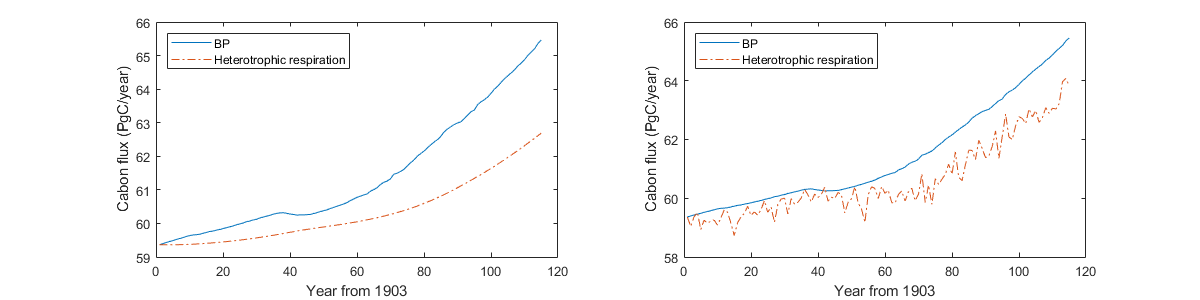

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Figure_title{1}='Constant temperature (only CO2 variation)';
Figure_title{2}='Yearly temperature and yearly CO2';
figure(1);
set(gcf,'Position', [1 1 1200 300])
for settings=1:2
subplot(1,2,settings)
year=1:length(Annual_record{settings}.NPP);
%yyaxis left
plot(year,Annual_record{settings}.NPP)
ylabel('Cabon flux (PgC/year)')
hold on
%yyaxis right
plot(year,Annual_record{settings}.Soil_Respiration,'-.')
hold off

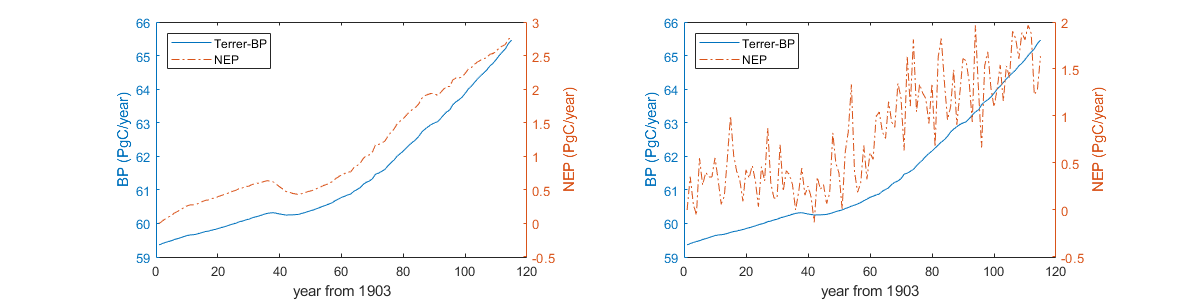

%ylabel('Soil respiration (PgC/year)')

xlabel('Year from 1903')

legend('BP','Heterotrophic respiration','Location','northwest')
%title({'Total NPP and soil respiration under',sprintf('%s',Figure_title{settings} )},'Interpreter', 'none')
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(2)
set(gcf,'Position', [1 1 1200 300])

for settings=1:2
subplot(1,2,settings)

year=1:length(Annual_record{settings}.NPP);
yyaxis left
plot(year,Annual_record{settings}.NPP)
ylabel('BP (PgC/year)')
yyaxis right
plot(year,Annual_record{settings}.Land_sink,'-.')
ylabel('NEP (PgC/year)')

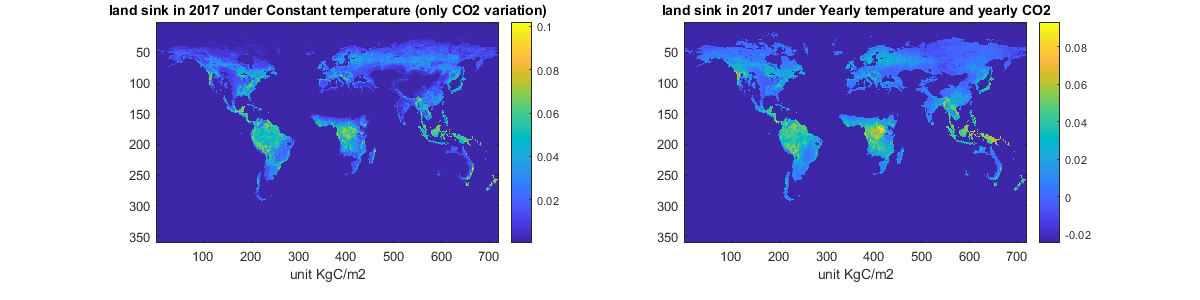


    xlabel('year from 1903')

legend('Terrer-BP','NEP','Location','northwest')
%title(sprintf('Time 1901-2017' ),'Interpreter', 'none')
%title({'Total NPP and Landsink under',sprintf('%s',Figure_title{settings} )},'Interpreter', 'none')
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(3)
set(gcf,'Position', [1 1 1200 300])

for settings=1:2
subplot(1,2,settings)

imagesc(Annual_record{settings}.Land_sinkmap(:,:,115))
colorbar
title(['land sink in 2017 under ' sprintf('%s',Figure_title{settings} )],'Interpreter', 'none')

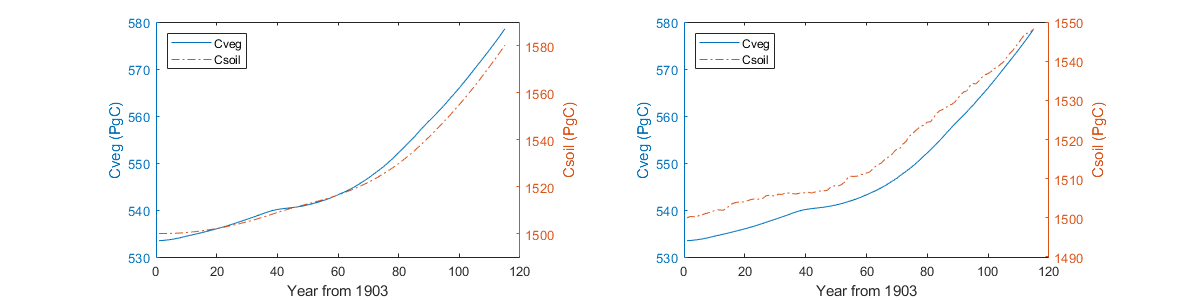

xlabel('unit KgC/m2')
scale = 0.1; % the below 4 lines solve the label cut-off problem
pos = get(gca, 'Position');
pos(2) = pos(2)+scale*pos(4);
pos(4) = (1-scale)*pos(4);
set(gca, 'Position', pos)
end
figure(4)
set(gcf,'Position', [1 1 1200 300])

for settings=1:2
subplot(1,2,settings)
year=1:length(Annual_record{settings}.NPP);
yyaxis left
plot(year,Annual_record{settings}.C_veg)
ylabel('Cveg (PgC)')
yyaxis right
plot(year,Annual_record{settings}.C_soil,'-.')

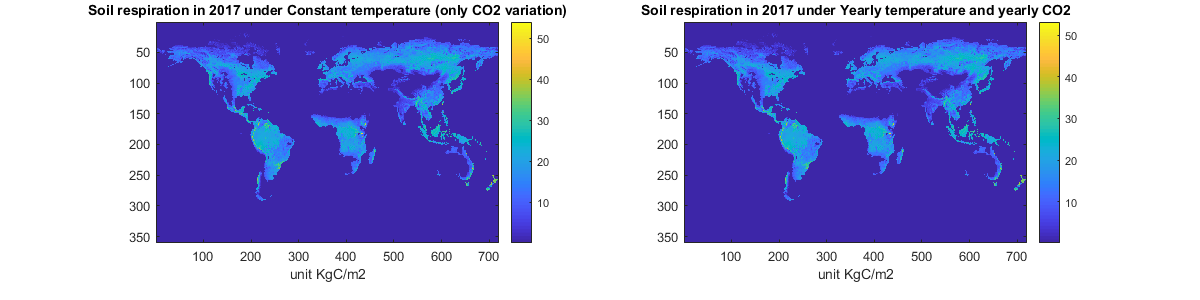

ylabel('Csoil (PgC)')

    xlabel('Year from 1903')

legend('Cveg','Csoil','Location','northwest')
%title({'Total Cveg and Csoil under',sprintf('%s',Figure_title{settings} )},'Interpreter', 'none')
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(5)
set(gcf,'Position', [1 1 1200 300])

for settings=1:2
subplot(1,2,settings)

imagesc(Annual_record{settings}.Csoil_map(:,:,115))
colorbar
title(['Soil respiration in 2017 under ' sprintf('%s',Figure_title{settings} )],'Interpreter', 'none')

xlabel('unit KgC/m2')
scale = 0.1; % the below 4 lines solve the label cut-off problem
pos = get(gca, 'Position');
pos(2) = pos(2)+scale*pos(4);
pos(4) = (1-scale)*pos(4);
set(gca, 'Position', pos)
end